%% gmrt_wind_davenport.m
% Compute kF, Fm, kf, Tm, Tw_RMS for GMRT mesh dish (D=45 m)
% and simulate gust time history using given Davenport filter

clear; close all; clc

% -----------------------
% INPUTS
% -----------------------
D       = 45;            % dish diameter (m)
R       = D/2;           % radius (m)
rho     = 1.15;          % air density (kg/m^3) - Khodad approx
Cd      = 0.60;          % mesh drag coefficient (dimensionless)
vn      = 3.15;          % mean wind speed (m/s)
z       = 23.16;         % antenna height (m)
z0      = 0.03;          % terrain roughness (m)
rcp_fac = 0.4;           % r_cp factor
rcp     = rcp_fac * R;   % effective moment arm (m)

% Davenport filter coefficients (new given ones)
b_hd = [0.413 0.1762 -1.402 0.1762 0.413];
a_hd = [1 19.38 -40.79 19.38 1];

% -----------------------
% AREA AND k_F
% -----------------------
A = pi * D^2 / 4;                  % projected area (m^2)
kF = 0.5 * rho * Cd * A;           % steady force coefficient (N/(m/s)^2)

% -----------------------
% TERRAIN COEFFICIENTS
% -----------------------
kappa = 1 / ( (2.5 * log(z / z0))^2 );
a     = sqrt(6 * kappa);

% -----------------------
% COMPUTE VALUES
% -----------------------
Fm      = kF * vn^2;               % steady (mean) force (N)
kf      = 2 * kF * a * vn^2;       % gust-force gain (N)
Tw_RMS  = kf * rcp;                % gust torque RMS (N*m)
Tm      = Fm * rcp;                % steady torque (N*m)

% -----------------------
% PRINT RESULTS
% -----------------------
fprintf('--- GMRT Mesh Dish Wind Load ---\n');

--- GMRT Mesh Dish Wind Load ---


fprintf('  Diameter D = %.2f m, Radius R = %.2f m\n', D, R);

  Diameter D = 45.00 m, Radius R = 22.50 m


fprintf('  Projected area A        = %.2f m^2\n', A);

  Projected area A        = 1590.43 m^2


fprintf('  k_F (steady coeff)      = %.2f N/(m/s)^2\n', kF);

  k_F (steady coeff)      = 548.70 N/(m/s)^2


fprintf('  F_m (steady force)      = %.2f N (%.2f kN)\n', Fm, Fm/1e3);

  F_m (steady force)      = 5444.46 N (5.44 kN)


fprintf('  k_f (gust gain, RMS)    = %.2f N (%.2f kN)\n', kf, kf/1e3);

  k_f (gust gain, RMS)    = 1604.59 N (1.60 kN)


fprintf('  T_m (steady torque)     = %.2f N*m (%.2f kN*m)\n', Tm, Tm/1e3);

  T_m (steady torque)     = 49000.17 N*m (49.00 kN*m)


fprintf('  T_w,RMS (gust torque)   = %.2f N*m (%.2f kN*m)\n\n', Tw_RMS, Tw_RMS/1e3);

  T_w,RMS (gust torque)   = 14441.35 N*m (14.44 kN*m)



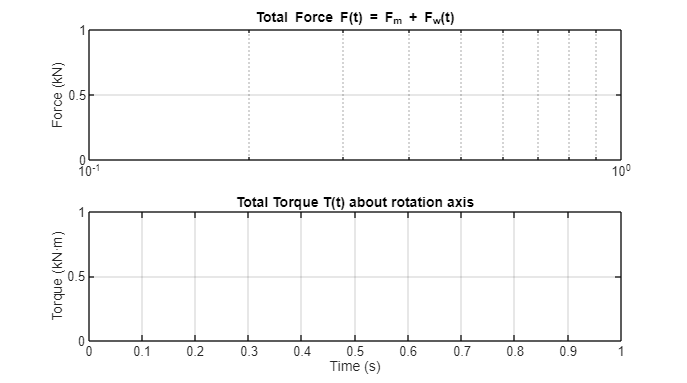


% -----------------------
% GUST TIME HISTORY USING DAVENPORT FILTER
% -----------------------
Ts   = 0.02;         % sampling time (s)
Tdur = 200;          % duration (s)
N    = round(Tdur / Ts);
t    = (0:N-1)' * Ts;

% Generate white noise and filter with Davenport filter
wn = randn(N,1);                     % unit white noise
delta_v0 = filter(b_hd, a_hd, wn);    % shape using Davenport filter

% Normalize to unit standard deviation
delta_v0 = delta_v0 / std(delta_v0);

% Compute forces and torques
Fw_t = kf * delta_v0;                 % gust force component (N)
F_t  = Fm + Fw_t;                     % total force (N)
T_t  = F_t * rcp;                     % total torque (N*m)

% -----------------------
% PLOTS
% -----------------------
figure('Name','Gust Force & Torque Time Series','NumberTitle','off','Position',[200 200 900 500]);
subplot(2,1,1);
plot(t, F_t/1e3); grid on;
ylabel('Force (kN)'); title('Total Force F(t) = F_m + F_w(t)');

subplot(2,1,2);
plot(t, T_t/1e3); grid on;
ylabel('Torque (kN·m)'); xlabel('Time (s)');
title('Total Torque T(t) about rotation axis');


% -----------------------
% RMS CHECK
% -----------------------
fprintf('Check: std(F_w) = %.2f N (should be ~k_f = %.2f N)\n', std(Fw_t), kf);

Check: std(F_w) = NaN N (should be ~k_f = 1604.59 N)
